t = load("t.txt");
x = transpose(load("x.txt")); % x(t) = A + B*t + C*sin(2*pi*t) + w(t)

Lineær modell / BLUE

H = [ones(length(t), 1), t(:), sin(2*pi*t(:))];
H_T=transpose(H);

S=inv((H_T*H))*H_T*x;  % [A ; B ; C]
CRLB=diag(inv(H_T*H)); % [Var(A) ; Var(B) ; Var(C)]

x_est=transpose(S(1)+S(2)*t+S(3)*sin(2*pi*t));
x_true=transpose(1+2*t+3*sin(2*pi*t));

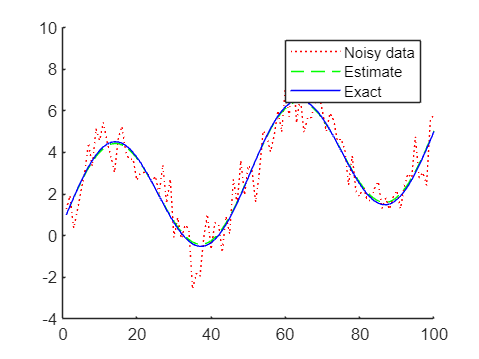

figure;
hold on;
plot(x,":","Color","r");
plot(x_est,"--","Color","g");
plot(x_true,"Color","b");
legend("Noisy data","Estimate","Exact");